path = "../data/type1/78/"

path = "../data/type1/78/"

recordFileName = "AUM-AL20_to_H60-L01.wav";
% recordFileName = "H60-L01_to_AUM-AL20.wav";
recordFile = path + recordFileName;
samplingRate = 44100;
fBegin = 2000;
fEnd = 6000;
chirpTimeMs = 100;
device1D = 0.01;
device2D = 0.01;
soundSpeed = 340;

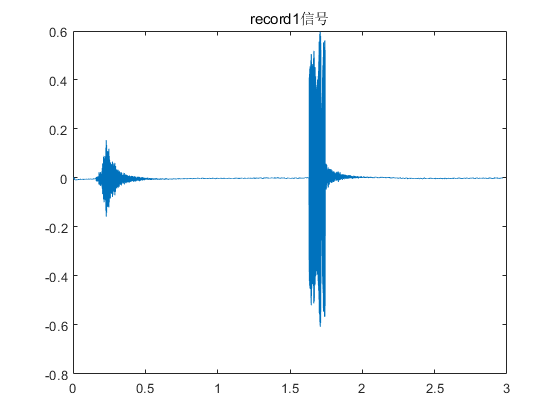

[originChirpT, originChirpY] = generateChirp(samplingRate,fBegin, fEnd, chirpTimeMs, 0);

[recordY, recordFs] = audioread(recordFile);
recordY = recordY(floor(0.05 * samplingRate):length(recordY));
recordLen = length(recordY);
%% 时域处理
recordT = (0:recordLen-1)/recordFs;
plot(recordT, recordY);
title("record1信号");


% 先利用互相关辅助将信号分割成两段
[c,lags] = xcorr(recordY, originChirpY)

c = 	1.0e+02 *

   0.000000000000000
   0.000000000000000
  -0.000000000000000
   0.000000000000000
   0.000000000000000
   0.000000000000000
  -0.000000000000000
  -0.000000000000000
  -0.000000000000000
  -0.000000000000000


lags =      -130977     -130976     -130975     -130974     -130973     -130972     -130971     -130970     -130969     -130968     -130967     -130966     -130965     -130964     -130963     -130962     -130961     -130960     -130959     -130958     -130957     -130956     -130955     -130954     -130953     -130952     -130951     -130950     -130949     -130948     -130947     -130946     -130945     -130944     -130943     -130942     -130941     -130940     -130939     -130938     -130937     -130936     -130935     -130934     -130933     -130932     -130931     -130930     -130929     -130928


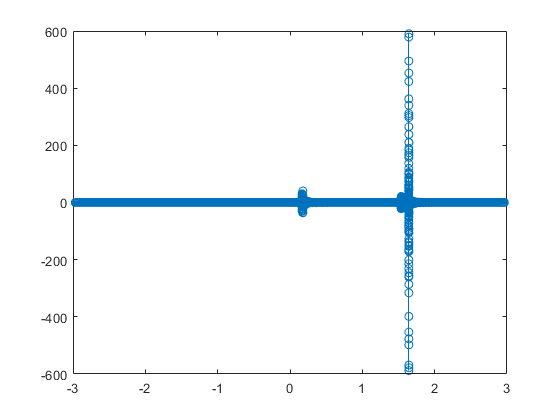

stem(lags / samplingRate, c)


radius = 20000; % 辅助区间的半径
[~, maxIndex1] = max(c);
rangeStart1 = maxIndex1 - radius

rangeStart1 =       183429


rangeEnd1 = maxIndex1 + radius;
% stem(lags,c);
tmp = [c(1:rangeStart1 - 1); zeros(radius * 2 + 1, 1); c(rangeEnd1 + 1:length(c))]

tmp =    0.000000000000000
   0.000000000000001
  -0.000000000000001
   0.000000000000001
   0.000000000000000
   0.000000000000000
  -0.000000000000001
  -0.000000000000001
  -0.000000000000002
  -0.000000000000001


% stem(lags, tmp);
[~, maxIndex2] = max(tmp);
if maxIndex1 < maxIndex2
    cutPoint = maxIndex2 - radius
else
    cutPoint = maxIndex1 - radius
end

cutPoint =       183429


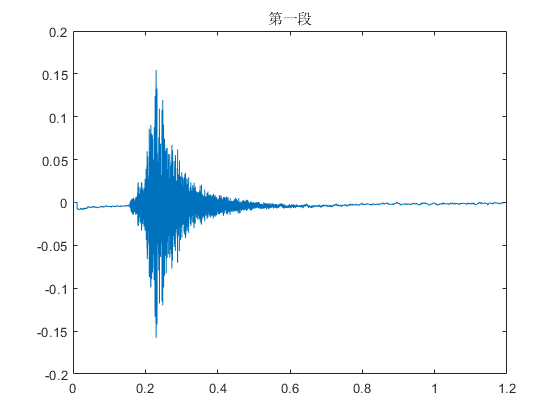


plot(recordT(1:cutPoint-1-recordLen),recordY(1:cutPoint-1-recordLen))
title("第一段")

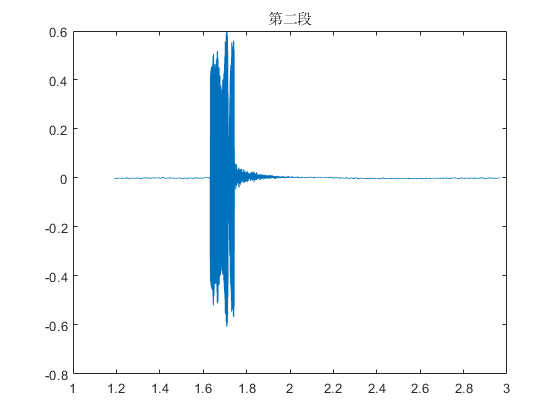

plot(recordT(cutPoint-recordLen:recordLen),recordY(cutPoint-recordLen:recordLen))
title("第二段")

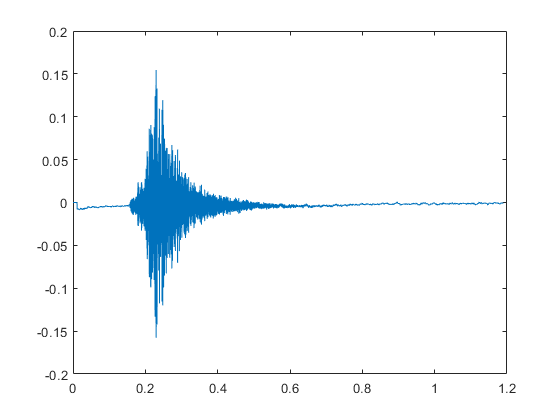

audiowrite(path+"part1_"+recordFileName,recordY(1:cutPoint-1-recordLen), samplingRate);
audiowrite(path+"part2_"+recordFileName,recordY(cutPoint-recordLen:recordLen), samplingRate);

[recordY2, recordFs] = audioread(path+"part1_"+recordFileName);
recordT = (0:length(recordY2)-1)/recordFs;
plot(recordT, recordY2);